Behavior of zero locations

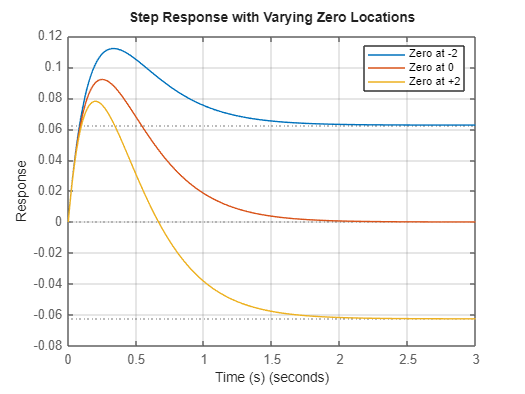

z_vals = [-1, 0, 1];        % Zero locations: left, origin, right
omega_n = 4;                % Natural frequency
zeta = 1;                 % Damping ratio

figure;
hold on;
for i = 1:length(z_vals)
    z = z_vals(i);
    
    % Numerator includes zero at s = z
    num = [1, -z];  % (s - z) becomes s - (-z) = s + z
    den = [1, 2*zeta*omega_n, omega_n^2];  % Standard 2nd-order denominator
    sys = tf(num, den);
    
    step(sys);
end

legend('Zero at -2', 'Zero at 0', 'Zero at +2');
title('Step Response with Varying Zero Locations');
xlabel('Time (s)');
ylabel('Response');
grid on;